**PART A - LOWPASS**

% Part A 
clear;
clc;
close all;

% Filter Specs
wp_a = 0.2 * pi;
ws_a = 0.3 * pi;
rp_a = 1;
as_a = 15;

% Analog Prototype Specs
T_a = 1;
omgP_a = 2 * tan(wp_a / 2);
omgS_a = 2 * tan(ws_a / 2);

% Analog Elliptical Filter order calculations
ep_a = sqrt(10^(rp_a/10)-1);
A_a = 10^(as_a/20);
omgC_a = omgP_a;
k_a = omgP_a / omgS_a;
k1_a = ep_a / sqrt(A_a*A_a-1);
capk_a = ellipke([k_a.^2 1-k_a.^2]);
capk1_a = ellipke([(k1_a.^2) 1-(k1_a.^2)]);
N_a = ceil(capk_a(1)*capk1_a(2) / (capk_a(2)*capk1_a(1)));

% Digital Filter Design 
wn_a = wp_a / pi;
[b_a, a_a] = ellip(N_a,rp_a,as_a,wn_a)

b_a =     0.1214   -0.0511   -0.0511    0.1214


a_a =     1.0000   -2.1112    1.7843   -0.5325


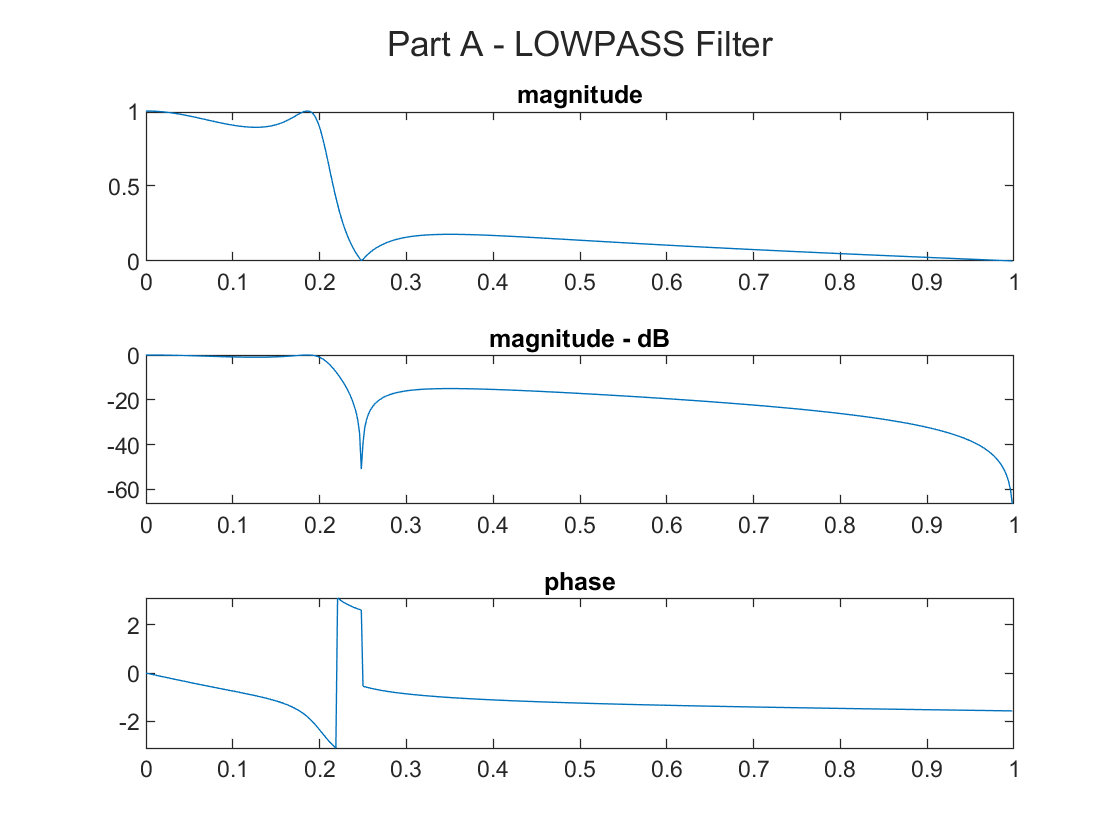

[blp, alp] = bilinear(b_a,a_a,1);
[h_a,w_a] = freqz(b_a,a_a);

% Plotting

figure(1)
t_a = tiledlayout(3,1);
title(t_a,'Part A - LOWPASS Filter')

nexttile
plot(w_a/pi,abs(h_a))
title('magnitude')   

nexttile
plot(w_a/pi,mag2db(abs(h_a)))
title('magnitude - dB')   

nexttile
plot(w_a/pi,angle(h_a))
title('phase')

**Part B - HIGHPASS**

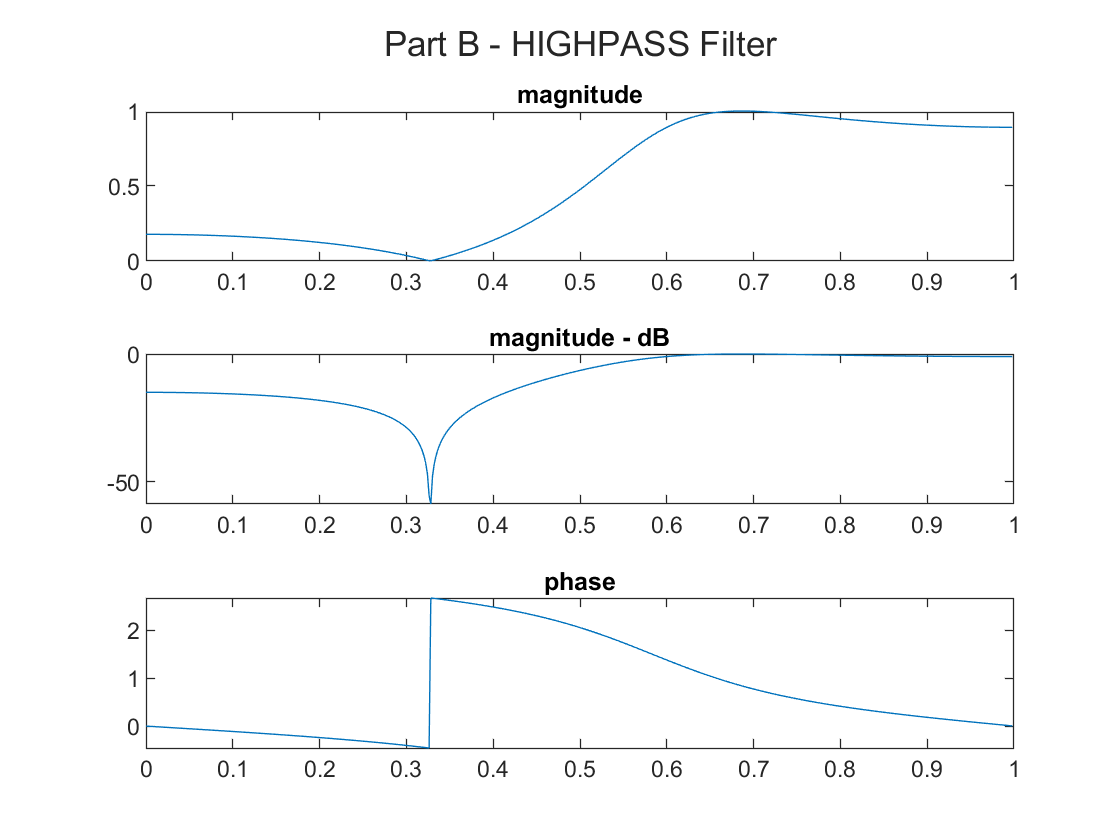

% Part A 
clear;
clc;
close all;

% Filter Specs
wp_b = 0.6 * pi;
ws_b = 0.4 * pi;
rp_b = 1;
as_b = 15;

%Analog Filter Design
[n_b, Wn_b] = ellipord(wp_b/pi, ws_b/pi, rp_b, as_b);
[b_b, a_b] = ellip(n_b,rp_b,as_b,Wn_b,"high");
[h_b, w_b] = freqz(b_b,a_b);

% Plotting

figure(2)
t_b = tiledlayout(3,1);
title(t_b,'Part B - HIGHPASS Filter')

nexttile
plot(w_b/pi,abs(h_b))
title('magnitude')   

nexttile
plot(w_b/pi,mag2db(abs(h_b)))
title('magnitude - dB')   

nexttile
plot(w_b/pi,angle(h_b))
title('phase')

**Part C - BANDPASS**

% Part C
clear;
clc;
close all;

% Filter Spces
wp_c = [0.4*pi 0.6*pi];
ws_c = [0.3*pi 0.75*pi];
rp_c = 1

rp_c = 1

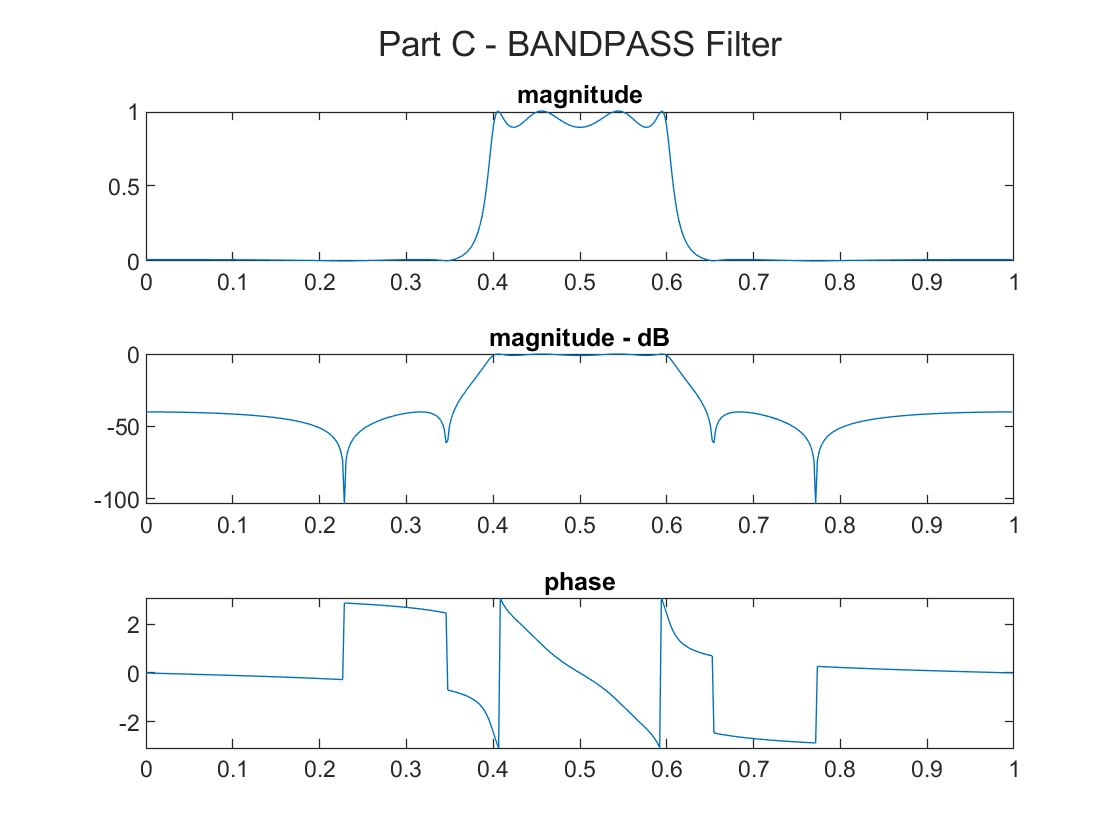

as_c = 40;

% Analog Filter Design 
[n_c, Wn_c] = ellipord(wp_c/pi, ws_c/pi, rp_c, as_c);
[b_c, a_c] = ellip(n_c,rp_c,as_c,Wn_c,"bandpass");
[h_c, w_c] = freqz(b_c,a_c);

% Plotting

figure(3)
t_b = tiledlayout(3,1);
title(t_b,'Part C - BANDPASS Filter')

nexttile
plot(w_c/pi,abs(h_c))
title('magnitude')   

nexttile
plot(w_c/pi,mag2db(abs(h_c)))
title('magnitude - dB')   

nexttile
plot(w_c/pi,angle(h_c))
title('phase')

**Part D - BANDSTOP**

% Part C
clear;
clc;
close all;

% Filter Spces
wp_c = [0.25*pi 0.8*pi];
ws_c = [0.4*pi 0.7*pi];
rp_c = 1

rp_c = 1

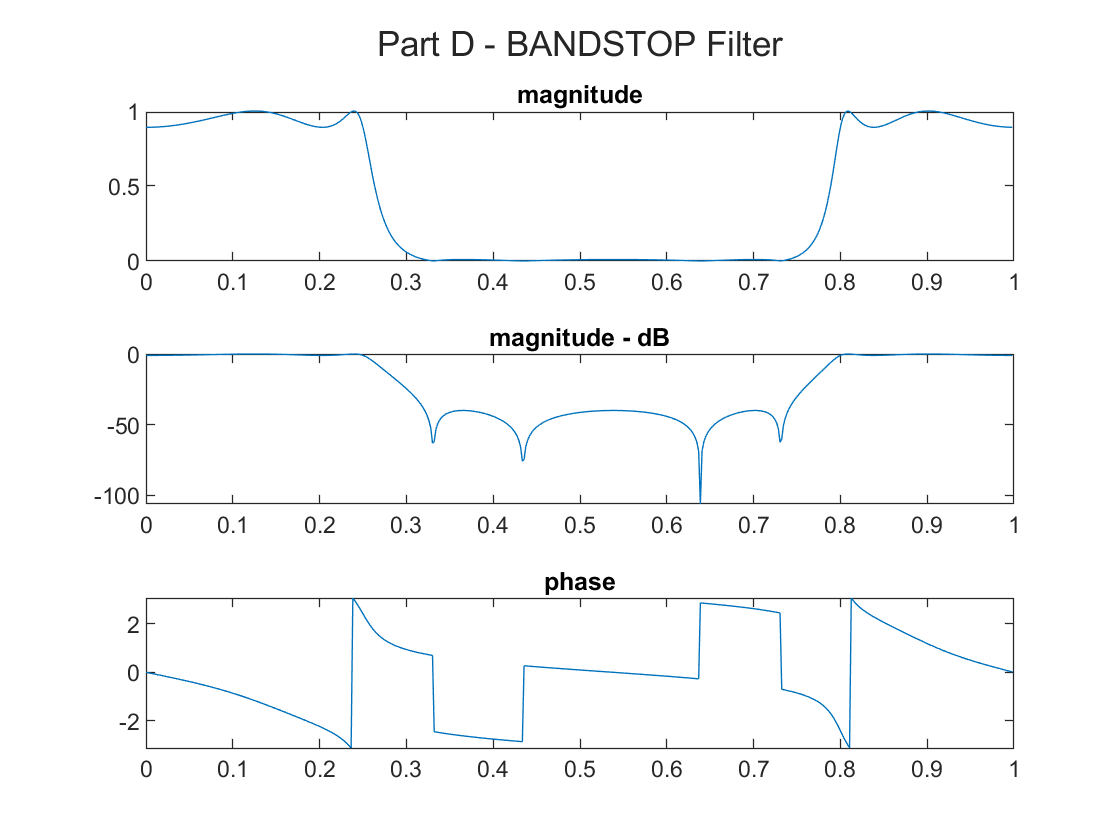

as_c = 40;

% Analog Filter Design 
[n_c, Wn_c] = ellipord(wp_c/pi, ws_c/pi, rp_c, as_c);
[b_c, a_c] = ellip(n_c,rp_c,as_c,Wn_c,"stop");
[h_c, w_c] = freqz(b_c,a_c);

% Plotting

figure(4)
t_b = tiledlayout(3,1);
title(t_b,'Part D - BANDSTOP Filter')

nexttile
plot(w_c/pi,abs(h_c))
title('magnitude')   

nexttile
plot(w_c/pi,mag2db(abs(h_c)))
title('magnitude - dB')   

nexttile
plot(w_c/pi,angle(h_c))
title('phase')